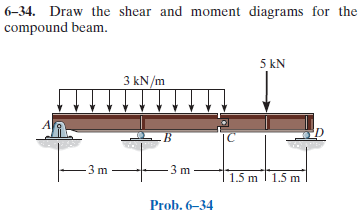

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-34P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-34P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 3*u.m);
b = b.add('hinge', 'force', 'Hc', 6*u.m);
b = b.add('concentrated', 'force', -5*u.kN, 7.5*u.m);
b = b.add('reaction', 'force', 'Rd', 9*u.m);
b = b.add('distributed', 'force', -3*u.kN/u.m, [0 6]*u.m);
b.L = 9*u.m;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(x-3\,m\right)\,\left(3\,x^{2}+19\,x\,m+57\,m^{2}\right)}{24\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ -\frac{\left(x-3\,m\right)\,\left(3\,x^{3}-73\,x^{2}\,m+609\,x\,m^{2}-828\,m^{3}\right)}{24\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(3\,m,6\,m\right]\\ \frac{20\,x^{3}-360\,x^{2}\,m+3717\,x\,m^{2}-18738\,m^{3}}{48\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(6\,m,\frac{15}{2}\,m\right]\\ \frac{\left(x-9\,m\right)\,\left(-20\,x^{2}+360\,x\,m+207\,m^{2}\right)}{48\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }\frac{15}{2}\,m<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{4\,x^{3}+10\,x^{2}\,m-57\,m^{3}}{8\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ -\frac{4\,x^{3}-82\,x^{2}\,m+552\,x\,m^{2}-885\,m^{3}}{8\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(3\,m,6\,m\right]\\ \frac{20\,x^{2}-240\,x\,m+1239\,m^{2}}{16\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(6\,m,\frac{15}{2}\,m\right]\\ -\frac{20\,x^{2}-360\,x\,m+1011\,m^{2}}{16\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }\frac{15}{2}\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -\frac{x\,\left(3\,x+5\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ -\frac{\left(x-6\,m\right)\,\left(3\,x-23\,m\right)}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(3\,m,6\,m\right]\\ \frac{5\,\left(x-6\,m\right)}{2}\,\mathrm{kN} & \text{ if }x\in \left(6\,m,\frac{15}{2}\,m\right]\\ -\frac{5\,\left(x-9\,m\right)}{2}\,\mathrm{kN} & \text{ if }\frac{15}{2}\,m<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -\frac{6\,x+5\,m}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 3\,m\\ -\frac{6\,x-41\,m}{2}\,\frac{\mathrm{kN}}{m} & \text{ if }x\in \left(3\,m,6\,m\right]\\ \frac{5}{2}\,\mathrm{kN} & \text{ if }x\in \left(6\,m,\frac{15}{2}\,m\right]\\ -\frac{5}{2}\,\mathrm{kN} & \text{ if }\frac{15}{2}\,m<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -3\,\frac{\mathrm{kN}}{m} & \text{ if }x\leq 6\,m\\ 0 & \text{ if }6\,m<x \end{array}\right.$$

# reactions and hinges

ra_vpa = vpa(ra) %#ok<NASGU> 

$$ra\_vpa = \left(\begin{array}{cc} \mathrm{Ra} & -2.5\,\mathrm{kN}\\ \mathrm{Rb} & 23.0\,\mathrm{kN}\\ \mathrm{Rd} & 2.5\,\mathrm{kN} \end{array}\right)$$

ha_vpa = vpa(ha) %#ok<NASGU> 

$$ha\_vpa = \left(\begin{array}{cc} \mathrm{Hc} & -2.5\,\mathrm{kN} \end{array}\right)$$

# shear and moment diagram

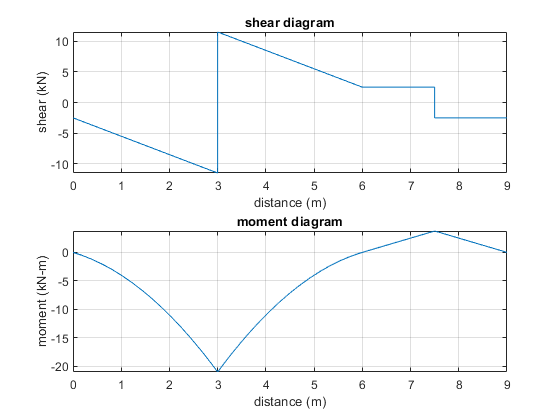

beam.shear_moment(m, v, [0 b.L], {'kN' 'm'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;
clear ra_vpa ha_vpa;